# Q1 Consider a network with 2 inputs, 1 hidden unit, but also with DIRECT connections from the input units to the output.  Show how such a network can conceivably compute XOR.

clear;
rs = 0; % set random seed
q1.smat = [0 0; 0 1; 1 0; 1 1];
q1.tmat = [0 1 1 0]';
% init network of 2 inputs, 1 hidden, 1 output
q1net0 = initnet3(2,1,1,2,2,rs);
% add weight of the dummy node (wih=[1,1] whout=1)
q1net0.wih = [q1net0.wih; 1,1];
q1net0.whout = [q1net0.whout 1];
q1net0

q1net0 = struct with fields:
      wih: [2×2 double]
    hbias: -0.7460
    whout: [0.8268 1]
    obias: 0.2647


q1net0.wih

ans =     0.6294    0.8116
    1.0000    1.0000


% train
q1net1k=bp3(q1net0,q1,1000,1,0,rs);
% check convergence
q1act1k = forw3(q1net1k,q1);
q1act1k.out

ans =     0.0083
    0.9965
    0.9967
    0.0072


## Q2 Use bp3.m to learn the task with 3 binary inputs that has target values of 0 for the inputs 000 and 111, and target values of 1 for the inputs 001, 010, 011, 100, 101, 110.  The network should have 3 input units, 2 hidden units, and 1 output unit.  Use forw3.m to check the activities of the outputs after training.  Show the hidden units on a 2 dimensional scatterplot --  color coded, if you can!

q2.smat=[0 0 0;0 0 1;0 1 0;0 1 1;1 0 0;1 0 1;1 1 0;1 1 1];
q2.tmat=[0 1 1 1 1 1 1 0]';
% init: 3 inputs, 2 hiddens, 1 ouput
q2net0 = initnet3(3,2,1,2,2,rs);
% train
q2net1k = bp3(q2net0,q2,1000,1,0,rs)

q2net1k = struct with fields:
      wih: [2×3 double]
    hbias: [-1.9443 6.6020]
    whout: [5.4058 3.5873]
    obias: -2.3910


% check output
q2act1k = forw3(q2net1k,q2);
q2act1k.out

ans =     0.0539
    0.9967
    0.9961
    0.9861
    0.9952
    0.9770
    0.8664
    0.4380


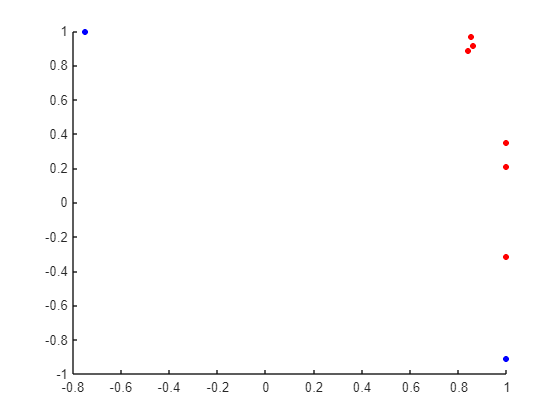

% plot
kolor = [q2.tmat,zeros(size(q2.tmat)),1-q2.tmat];
scatter(q2act1k.hid(:,1),q2act1k.hid(:,2),10,kolor,"filled")

## Q3 Repeat exercise 2 with 4 binary inputs --> target values of 0 for inputs 0000 and 1111 target 1 for all other (14) inputs.

% generate all possible combination of input 4
q3.smat = ff2n(4);
% set first (0000) and last (1111) output to 1
q3.tmat = zeros(16,1);
q3.tmat(1) = 1;
q3.tmat(16) = 1;
% init 4 inputs, 2 hiddens, 1 out
q3net0 = initnet3(4,2,1,2,2,rs);
% train
q3net1k = bp3(q3net0,q3,1000,1,0,rs);
% check output
q3act1k = forw3(q3net1k,q3);
q3act1k.out

ans =     0.9451
    0.0072
    0.0073
    0.0063
    0.0065
    0.0240
    0.0058
    0.0871
    0.0060
    0.0142


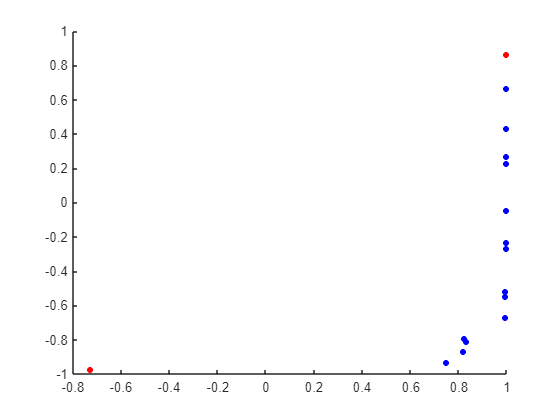

kolor = [q3.tmat,zeros(size(q3.tmat)),1-q3.tmat];
scatter(q3act1k.hid(:,1),q3act1k.hid(:,2),10,kolor,"filled")

## Q4 Train a network on the XOR task.  Plot the representations of the training set in the hidden unit space. Challenge: Create a contour plot of the output unit's response in the stimulus space.

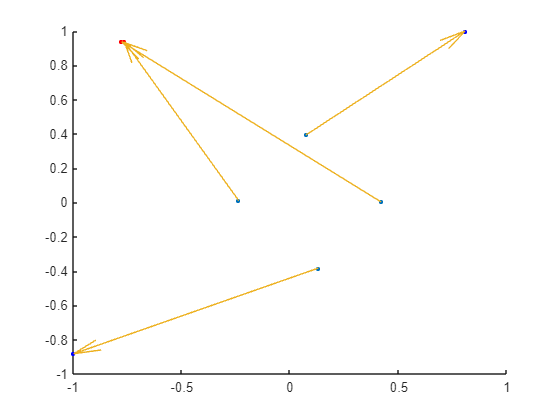

% train XOR
xor.smat = [0 0;0 1;1 0;1 1];
xor.tmat = [0 1 1 0]';
xornet0 = initnet3(2,2,1,2,2,rs);
xoract0 = forw3(xornet0,xor);
xornet1k = bp3(xornet0,xor,1000,1,0,rs);
xoract1k = forw3(xornet1k,xor);
% set color
kolor = [xor.tmat,zeros(size(xor.tmat)),1-xor.tmat];

figure
hold on
% draw training set
scatter(xoract0.hid(:,1),xoract0.hid(:,2),10,"filled")
% draw trained set
scatter(xoract1k.hid(:,1),xoract1k.hid(:,2),10,kolor,"filled")
% quivers point from untrained to trained
drawArrow = @(x1,y1,x2,y2) quiver(x1,y1,x2-x1,y2-y1,0);
drawArrow(xoract0.hid(:,1),xoract0.hid(:,2),xoract1k.hid(:,1),xoract1k.hid(:,2))
hold off

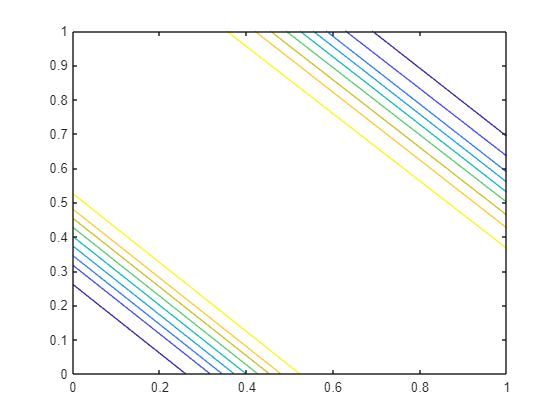


figure
% build input
x = 0:0.1:1;
y = 0:0.1:1;
% generate all [x y] combination
stims=combvec(x,y)';
% obtain output from the network
netwk=xornet1k;
hid=layersigpn(stims,netwk.wih,netwk.hbias) ;
out=layersig01(hid,netwk.whout,netwk.obias) ;
% contour input prep
[X,Y]= meshgrid(x,y);
contour(X,Y,griddata(stims(:,1),stims(:,2),out,X,Y))